# Robot PKM

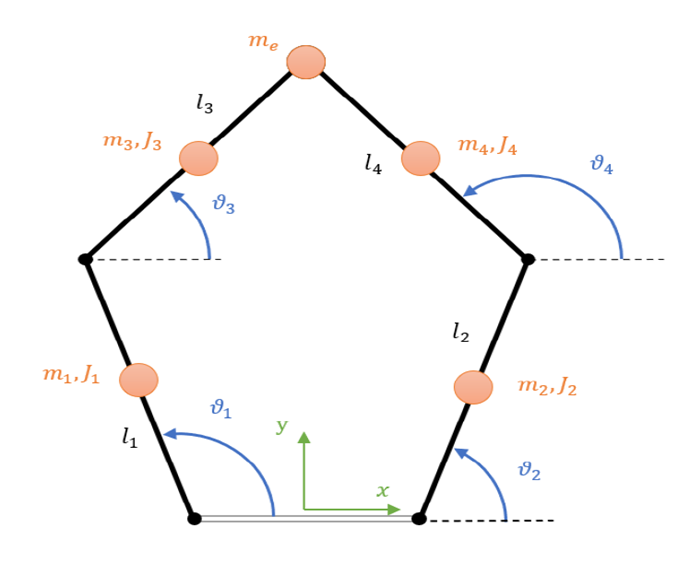

##   Definizione dati e informazioni utili manipolatore 

[PKM] = Define_Robot();

% Definizione parametri di test
theta1 = deg2rad(120); % Condizione iniziale posizione Theta1
theta2 = deg2rad(60); %  Condizione iniziale posizione Theta2
thetaV = deg2rad(720); % Angolo proprio della vite

theta1_p = 0; %  Condizione iniziale velocità theta1
theta2_p = 0; %  Condizione iniziale velocità tehta2
thetaV_p = 0; % Velocita thetav di prova

theta1_pp = 0; %  Condizione iniziale accelerazione theta1
theta2_pp = 0; %  Condizione iniziale accelarazione theta2
thetaV_pp = 0; % Accelerazione thetav di prova

## Legge di moto

Ldm_theta = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


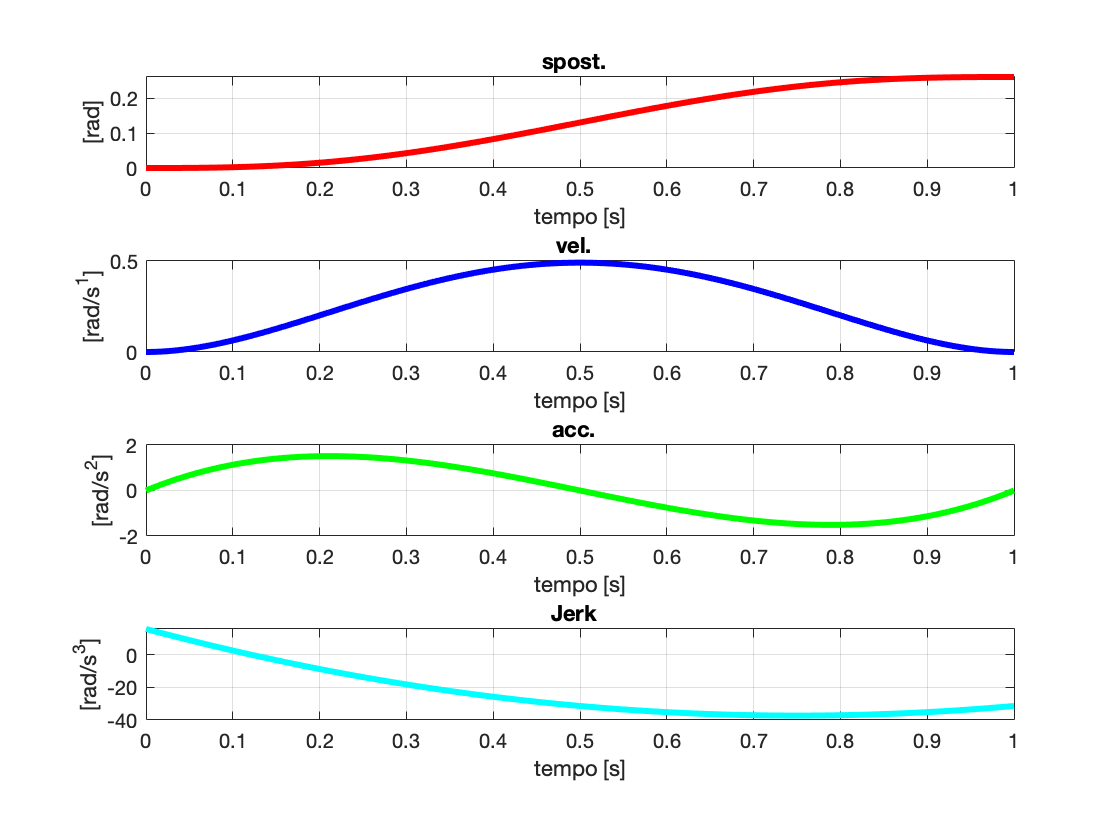

Ldm_theta1 = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


[Ldm_theta1] = Define_ldm(deg2rad(15), 'pol345') % Definisce una legge di moto data l'alzata in gradi per theta1

Ldm_theta = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


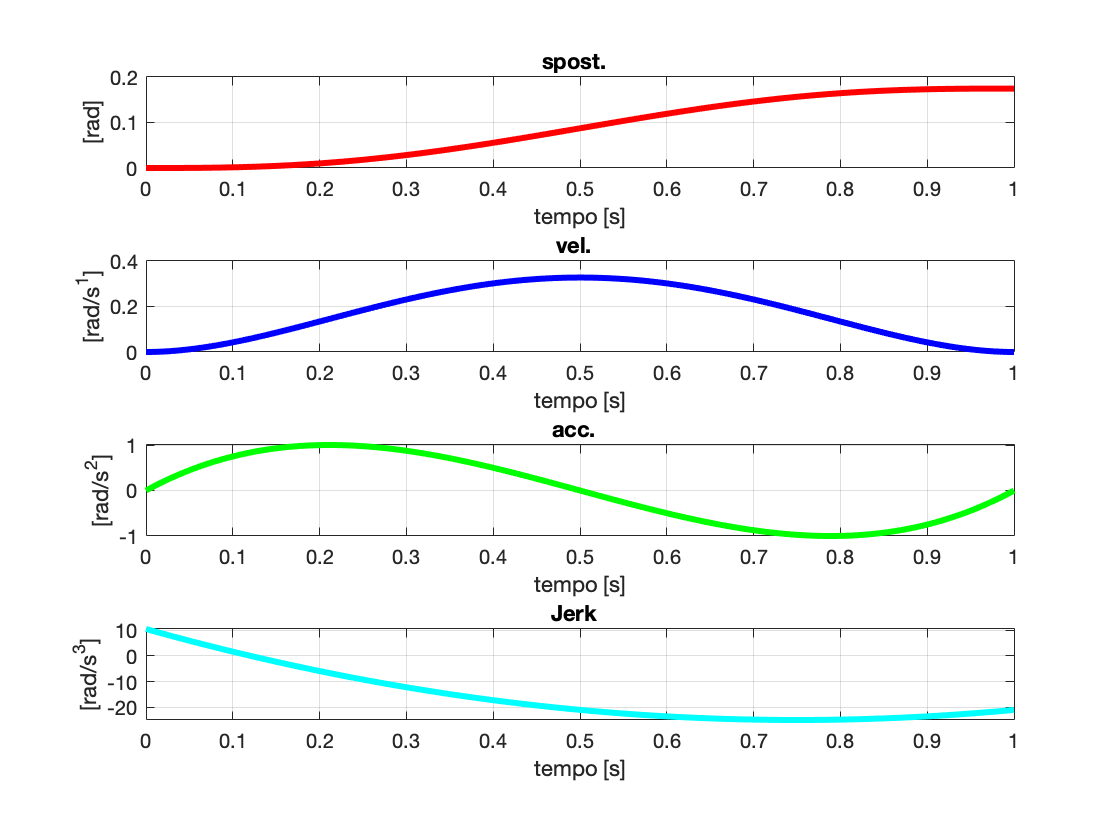

Ldm_theta2 = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


[Ldm_theta2] = Define_ldm(deg2rad(10), 'pol345') % Definisce una legge di moto data l'alzata in gradi per theta2

Ldm_theta = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


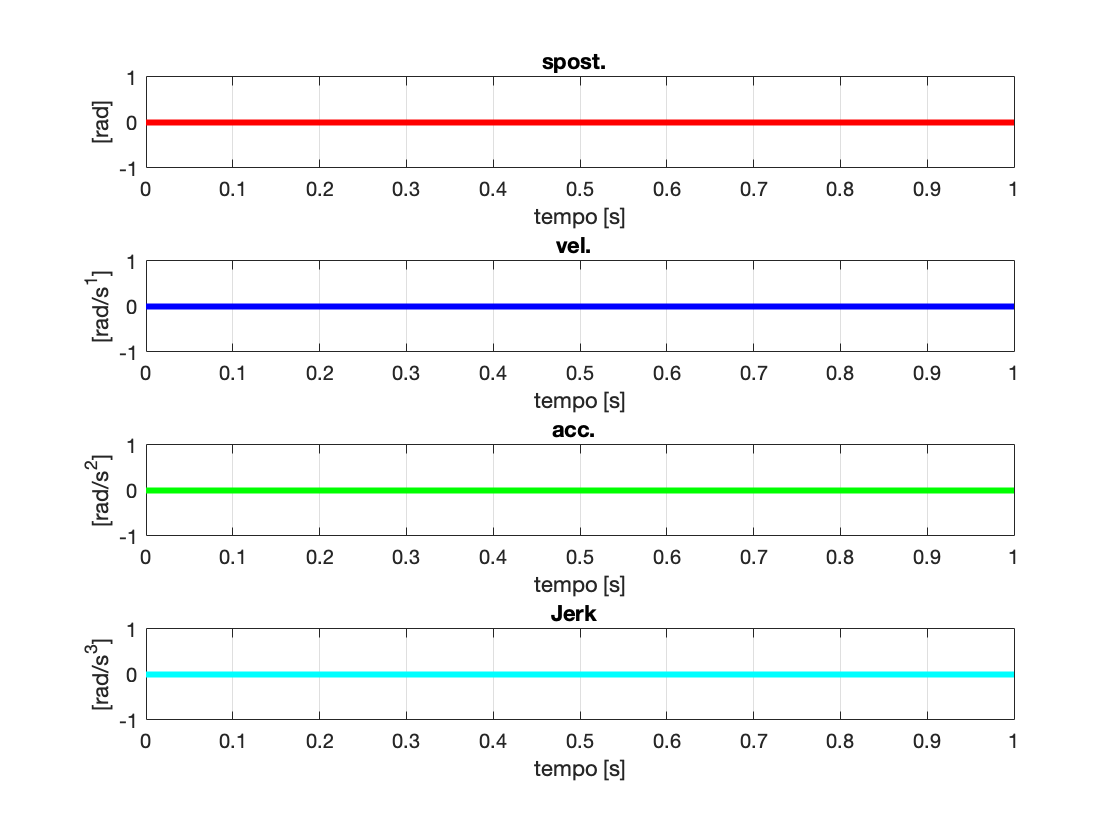

Ldm_thetav = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


[Ldm_thetav] = Define_ldm(0, 'pol357') % Definisce una legge di moto per la vite


theta1ldm = theta1 + Ldm_theta1.moto.data{1,1}.v;
theta2ldm = theta2 + Ldm_theta2.moto.data{1,1}.v;
thetavldm = thetaV + Ldm_thetav.moto.data{1,1}.v;
PKM.ta = Ldm_theta1.vldm{1,1}.ta+Ldm_theta1.vldm{1,2}.ta+Ldm_theta1.vldm{1,3}.ta+Ldm_theta1.vldm{1,4}.ta;

Theta = [theta1ldm; theta2ldm; thetavldm]

Theta =     2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0946    2.0946    2.0946    2.0946    2.0946    2.0946    2.0946    2.0946    2.0947    2.0947
    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0474    1.0474    1.0474 

## Cinematica diretta

**Analisi di posizione**

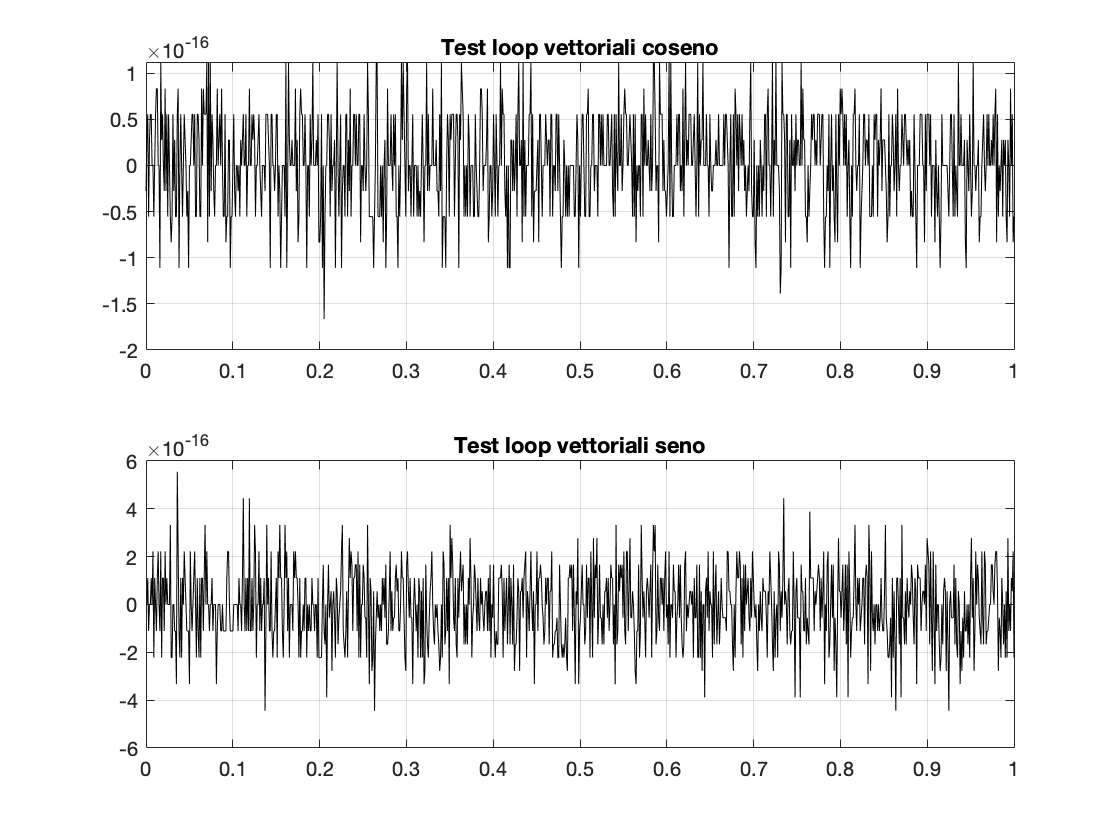

P =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0

theta3 =     0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356


theta4 =     2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6062    2.6062    2.6062    2.6062    2.6062    2.6062    2.6062    2.6062    2.6062    2.6062    2.6062    2.6063    2.6063    2.6063


E1 =    -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2151   -0.2151   -0.2151   -0.2151
    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    

E2 =     0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150
    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    

[P, theta3, theta4, E1, E2] = Cinematica_Diretta_Posizione(PKM, theta1ldm, theta2ldm, thetavldm)

**Rappresentazione grafica**

%animation(PKM.link.d, PKM.link.l,theta1ldm,theta2ldm,theta3,theta4)

**Analisi di velocità**

theta1ldm_p = theta1_p + Ldm_theta1.moto.data{2,1}.v;
theta2ldm_p = theta2_p + Ldm_theta2.moto.data{2,1}.v;
thetavldm_p = thetaV_p + Ldm_thetav.moto.data{2,1}.v;

[P_p, J, P_pM] = Cinematica_Diretta_Velocita2(PKM, theta1ldm, theta2ldm, theta1ldm_p,theta2ldm_p,thetavldm_p,P)

P_p =          0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0006   -0.0007   -0.0007   -0.0008   -0.0009   -0.0010   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0016   -0.0017   -0.0018   -0.0019   -0.0021   -0.0022   -0.0023   -0.0024   -0.0025   -0.0027   -0.0028   -0.0029   -0.0031   -0.0032   -0.0034   -0.0035   -0.0037   -0.0038   -0.0040   -0.0041
         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0009   -0.0009   -0.0009   -0.0010   -0.0010   -0.0011   -0.0011   -0.0012   -0.0012   -0.0013   -0.0013   

J =    -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453
   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0

P_pM =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0006   -0.0006   -0.0007   -0.0008   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0016   -0.0017   -0.0018   -0.0019   -0.0020   -0.0021   -0.0022   -0.0024   -0.0025   -0.0026   -0.0027   -0.0029   -0.0030   -0.0032   -0.0033   -0.0034   -0.0036   -0.0037   -0.0039   -0.0041   -0.0042


Theta_p = [theta1ldm_p;theta2ldm_p;thetavldm_p]

Theta_p =          0    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0011    0.0013    0.0015    0.0017    0.0020    0.0022    0.0025    0.0027    0.0030    0.0033    0.0036    0.0040    0.0043    0.0047    0.0050    0.0054    0.0058    0.0062    0.0067    0.0071    0.0076    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0111    0.0116    0.0122    0.0127    0.0133    0.0139    0.0145    0.0152    0.0158    0.0164    0.0171
         0    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0006    0.0007    0.0009    0.0010    0.0011    0.0013    0.0015    0.0016    0.0018    0.0020    0.0022    0.0024    0.0026    0.0029    0.0031    0.0034    0.0036    0.0039    0.0042    0.0044    0.0047    0.0050    0.0053    0.0057    0.0060    0.0063    0.0067    0.0070    0.0074    0.0077    0.0081    0.0085    0.0089    0.0093    0.0097    0.0101    0.0105    0.011

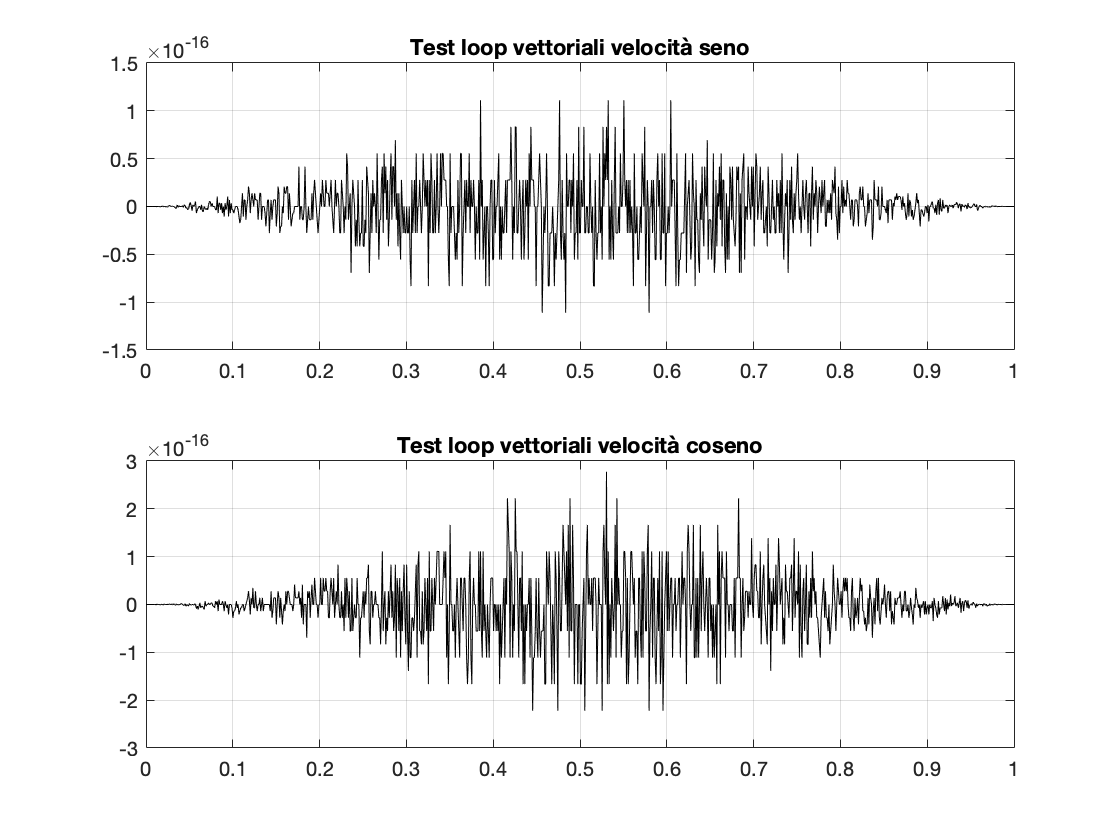

theta3_p =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0009    0.0009    0.0010    0.0011    0.0012    0.0013    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0025    0.0026    0.0027    0.0028    0.0029    0.0031    0.0032    0.0033    0.0034


theta4_p =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0010    0.0012    0.0013    0.0015    0.0017    0.0019    0.0021    0.0023    0.0026    0.0028    0.0030    0.0033    0.0036    0.0039    0.0042    0.0045    0.0048    0.0051    0.0054    0.0058    0.0061    0.0065    0.0069    0.0073    0.0077    0.0081    0.0085    0.0089    0.0093    0.0098    0.0102    0.0107    0.0112    0.0116    0.0121    0.0126    0.0131


J34 =    -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393
    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   

[theta3_p,theta4_p,J34] = Theta34p(PKM,theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p)

**Analisi di accelerazione**

theta1ldm_pp = theta1_p + Ldm_theta1.moto.data{3,1}.v;
theta2ldm_pp = theta2_p + Ldm_theta2.moto.data{3,1}.v;
thetavldm_pp = thetaV_p + Ldm_thetav.moto.data{3,1}.v;

Theta_pp = [theta1ldm_pp;theta2ldm_pp;thetavldm_pp]

Theta_pp =          0    0.0157    0.0313    0.0467    0.0621    0.0774    0.0926    0.1078    0.1228    0.1377    0.1525    0.1673    0.1819    0.1965    0.2110    0.2253    0.2396    0.2538    0.2679    0.2819    0.2958    0.3097    0.3234    0.3370    0.3506    0.3641    0.3775    0.3907    0.4039    0.4170    0.4301    0.4430    0.4558    0.4686    0.4813    0.4938    0.5063    0.5187    0.5310    0.5433    0.5554    0.5675    0.5794    0.5913    0.6031    0.6148    0.6264    0.6380    0.6494    0.6608
         0    0.0105    0.0208    0.0312    0.0414    0.0516    0.0618    0.0718    0.0819    0.0918    0.1017    0.1115    0.1213    0.1310    0.1406    0.1502    0.1597    0.1692    0.1786    0.1879    0.1972    0.2064    0.2156    0.2247    0.2337    0.2427    0.2516    0.2605    0.2693    0.2780    0.2867    0.2953    0.3039    0.3124    0.3208    0.3292    0.3376    0.3458    0.3540    0.3622    0.3703    0.3783    0.3863    0.3942    0.4021    0.4099    0.4176    0.4253    0.43

[P_pp] = Cinematica_Diretta_Accelerazione2(PKM,Theta, Theta_p, Theta_pp, P, P_p)

P_pp =          0   -0.0038   -0.0076   -0.0113   -0.0151   -0.0188   -0.0224   -0.0261   -0.0297   -0.0334   -0.0370   -0.0405   -0.0441   -0.0476   -0.0511   -0.0546   -0.0580   -0.0615   -0.0649   -0.0683   -0.0717   -0.0750   -0.0783   -0.0816   -0.0849   -0.0882   -0.0914   -0.0946   -0.0978   -0.1010   -0.1042   -0.1073   -0.1104   -0.1135   -0.1166   -0.1196   -0.1226   -0.1256   -0.1286   -0.1316   -0.1345   -0.1374   -0.1403   -0.1432   -0.1461   -0.1489   -0.1517   -0.1545   -0.1573   -0.1600
         0   -0.0013   -0.0026   -0.0038   -0.0051   -0.0063   -0.0076   -0.0088   -0.0100   -0.0112   -0.0125   -0.0137   -0.0149   -0.0160   -0.0172   -0.0184   -0.0196   -0.0207   -0.0219   -0.0230   -0.0242   -0.0253   -0.0264   -0.0275   -0.0286   -0.0297   -0.0308   -0.0319   -0.0330   -0.0341   -0.0351   -0.0362   -0.0372   -0.0383   -0.0393   -0.0403   -0.0414   -0.0424   -0.0434   -0.0444   -0.0454   -0.0464   -0.0474   -0.0483   -0.0493   -0.0503   -0.0512   -0.0522   -0.0531  

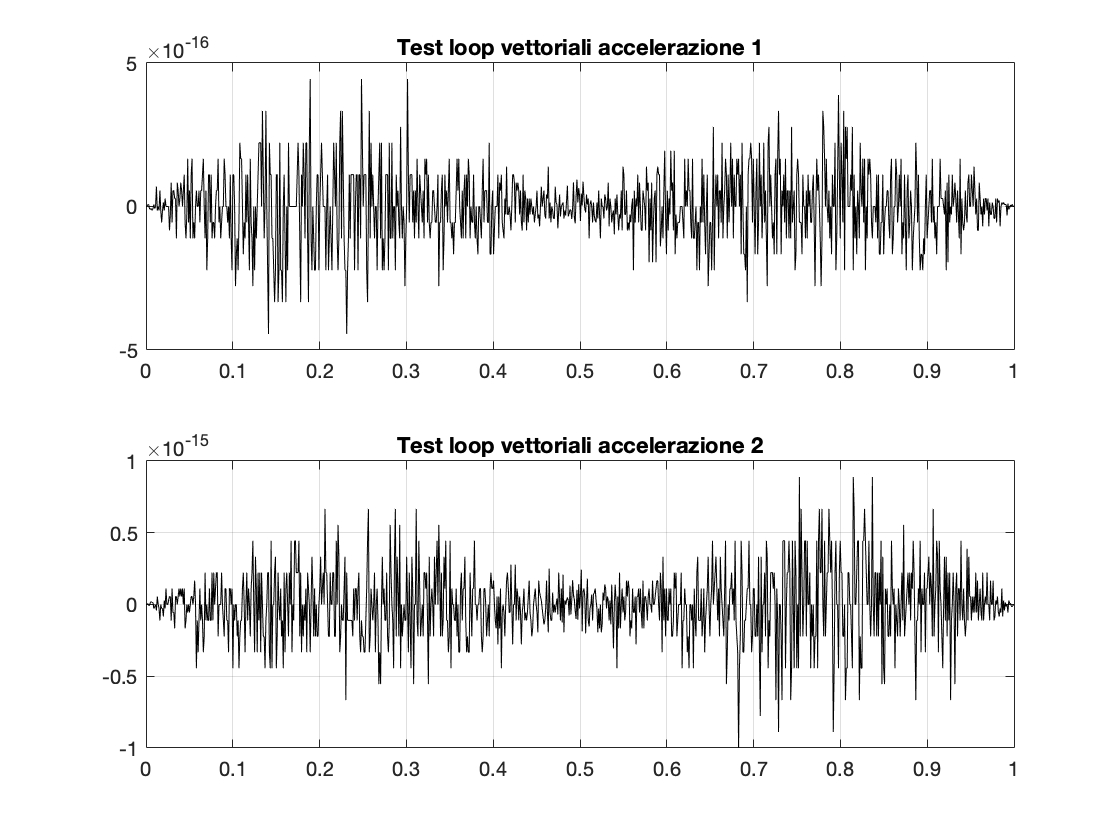

theta3_pp =          0    0.0032    0.0063    0.0094    0.0125    0.0156    0.0187    0.0217    0.0248    0.0278    0.0308    0.0337    0.0367    0.0396    0.0425    0.0454    0.0483    0.0512    0.0540    0.0569    0.0597    0.0624    0.0652    0.0680    0.0707    0.0734    0.0761    0.0788    0.0815    0.0841    0.0867    0.0894    0.0919    0.0945    0.0971    0.0996    0.1021    0.1046    0.1071    0.1096    0.1121    0.1145    0.1169    0.1193    0.1217    0.1241    0.1264    0.1288    0.1311    0.1334


theta4_pp =          0    0.0120    0.0240    0.0359    0.0477    0.0594    0.0711    0.0827    0.0942    0.1057    0.1171    0.1284    0.1396    0.1508    0.1619    0.1729    0.1839    0.1948    0.2056    0.2163    0.2270    0.2376    0.2482    0.2586    0.2690    0.2794    0.2896    0.2998    0.3100    0.3200    0.3300    0.3399    0.3498    0.3596    0.3693    0.3789    0.3885    0.3980    0.4075    0.4169    0.4262    0.4354    0.4446    0.4537    0.4628    0.4718    0.4807    0.4895    0.4983    0.5070


J34p =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0002    0.0000    0.0002    0.0000    0.0003    0.0001    0.0003    0.0001    0.0004    0.0001    0.0005    0.0001    0.0005    0.0001    0.0006    0.0001    0.0007    0.0001    0.0008    0.0001    0.0009    0.0002    0.0010    0.0002    0.0011    0.0002    0.0012    0.0002    0.0013    0.0002    0.0014    0.0003    0.0015
         0         0    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0001   -0.0001    0.0001   -0.0002    0.0001   -0.0002    0.0002   -0.0003    0.0002   -0.0004    0.0003   -0.0005    0.0003   -0.0006    0.0004   -0.0007    0.0005   -0.0008    0.0005   -0.0010    0.0006   -0.0011    0.0007   -0.0012    0.0008   -0.0014    0.0009   -0.0016    0.0010   -0.0017    0.0011   -0.0019    0.0012   -0.0021    0.0013   -0.0023    0.0014   -0.0025    0.0016  

[theta3_pp,theta4_pp,J34p] = Theta34pp(theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p,...
    theta3_p,theta4_p,theta1ldm_pp, theta2ldm_pp,J34)


[C1_p, C2_p, C1_pp, C2_pp, E1_p, E1_pp, J1, J1p, J2, J2p, J3, J3p, J4, J4p, JE, JEp,P_p34, P_pp34] = Jacobiani(PKM, Theta, Theta_p, theta3, theta4, theta3_p, theta4_p, J34, J34p, P_pp, Theta_pp);

C1_p =          0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0007   -0.0008   -0.0008   -0.0009   -0.0009   -0.0010   -0.0010   -0.0011   -0.0011   -0.0012   -0.0013   -0.0013   -0.0014   -0.0014   -0.0015   -0.0016   -0.0016   -0.0017   -0.0018   -0.0018
         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008   -0.0009   -0.0009   -0.0009   -0.0010   -0.0010  

C2_p =          0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006   -0.0006   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008   -0.0009   -0.0009   -0.0010   -0.0010   -0.0010   -0.0011   -0.0011   -0.0012   -0.0012
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007  

C1_pp =          0   -0.0017   -0.0034   -0.0051   -0.0067   -0.0084   -0.0100   -0.0117   -0.0133   -0.0149   -0.0165   -0.0181   -0.0197   -0.0213   -0.0228   -0.0244   -0.0259   -0.0275   -0.0290   -0.0305   -0.0320   -0.0335   -0.0350   -0.0365   -0.0380   -0.0394   -0.0409   -0.0423   -0.0437   -0.0451   -0.0466   -0.0480   -0.0493   -0.0507   -0.0521   -0.0535   -0.0548   -0.0561   -0.0575   -0.0588   -0.0601   -0.0614   -0.0627   -0.0640   -0.0653   -0.0665   -0.0678   -0.0690   -0.0703   -0.0715
         0   -0.0010   -0.0020   -0.0029   -0.0039   -0.0048   -0.0058   -0.0067   -0.0077   -0.0086   -0.0095   -0.0105   -0.0114   -0.0123   -0.0132   -0.0141   -0.0150   -0.0159   -0.0167   -0.0176   -0.0185   -0.0194   -0.0202   -0.0211   -0.0219   -0.0228   -0.0236   -0.0244   -0.0253   -0.0261   -0.0269   -0.0277   -0.0285   -0.0293   -0.0301   -0.0309   -0.0317   -0.0324   -0.0332   -0.0340   -0.0347   -0.0355   -0.0362   -0.0370   -0.0377   -0.0385   -0.0392   -0.0399   -0.0406 

C2_pp =          0   -0.0011   -0.0023   -0.0034   -0.0045   -0.0056   -0.0067   -0.0078   -0.0089   -0.0099   -0.0110   -0.0121   -0.0131   -0.0142   -0.0152   -0.0163   -0.0173   -0.0183   -0.0193   -0.0203   -0.0214   -0.0223   -0.0233   -0.0243   -0.0253   -0.0263   -0.0272   -0.0282   -0.0292   -0.0301   -0.0310   -0.0320   -0.0329   -0.0338   -0.0347   -0.0356   -0.0365   -0.0374   -0.0383   -0.0392   -0.0401   -0.0410   -0.0418   -0.0427   -0.0435   -0.0444   -0.0452   -0.0461   -0.0469   -0.0477
         0    0.0007    0.0013    0.0019    0.0026    0.0032    0.0039    0.0045    0.0051    0.0057    0.0064    0.0070    0.0076    0.0082    0.0088    0.0094    0.0100    0.0106    0.0112    0.0117    0.0123    0.0129    0.0135    0.0140    0.0146    0.0152    0.0157    0.0163    0.0168    0.0174    0.0179    0.0185    0.0190    0.0195    0.0200    0.0206    0.0211    0.0216    0.0221    0.0226    0.0231    0.0236    0.0241    0.0246    0.0251    0.0256    0.0261    0.0266    0.0270 

E1_p =          0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0006   -0.0007   -0.0007   -0.0008   -0.0009   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0014   -0.0015   -0.0016   -0.0017   -0.0018   -0.0019   -0.0021   -0.0022   -0.0023   -0.0024   -0.0025   -0.0026   -0.0028   -0.0029   -0.0030   -0.0031   -0.0033   -0.0034   -0.0036   -0.0037
         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0007   -0.0008   -0.0008   -0.0009   -0.0009   -0.0010   -0.0011   -0.0011   -0.0012   -0.0012   -0.0013   -0.0014   -0.0015   -0.0015   -0.0016   -0.0017   -0.0017   -0.0018   -0.0019   -0.0020   -0.0021  

E1_pp =          0   -0.0034   -0.0068   -0.0101   -0.0135   -0.0168   -0.0201   -0.0233   -0.0266   -0.0298   -0.0330   -0.0362   -0.0394   -0.0425   -0.0457   -0.0488   -0.0519   -0.0550   -0.0580   -0.0610   -0.0640   -0.0670   -0.0700   -0.0730   -0.0759   -0.0788   -0.0817   -0.0846   -0.0874   -0.0903   -0.0931   -0.0959   -0.0987   -0.1014   -0.1042   -0.1069   -0.1096   -0.1123   -0.1150   -0.1176   -0.1202   -0.1228   -0.1254   -0.1280   -0.1305   -0.1331   -0.1356   -0.1381   -0.1406   -0.1430
         0   -0.0020   -0.0039   -0.0058   -0.0078   -0.0097   -0.0116   -0.0135   -0.0153   -0.0172   -0.0191   -0.0209   -0.0227   -0.0246   -0.0264   -0.0282   -0.0300   -0.0317   -0.0335   -0.0352   -0.0370   -0.0387   -0.0404   -0.0421   -0.0438   -0.0455   -0.0472   -0.0489   -0.0505   -0.0521   -0.0538   -0.0554   -0.0570   -0.0586   -0.0602   -0.0618   -0.0633   -0.0649   -0.0664   -0.0680   -0.0695   -0.0710   -0.0725   -0.0740   -0.0755   -0.0769   -0.0784   -0.0798   -0.0813 

J1 =    -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0
   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625    

J1p =          0         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0001         0    0.0001         0    0.0001         0    0.0001         0    0.0001         0    0.0001         0    0.0001         0    0.0002         0    0.0002         0    0.0002         0    0.0002         0    0.0002         0    0.0002         0    0.0003         0
         0         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0002         0   -0.0002         0   -0.0002         0   -0.0002         0   -0.0003         0   -0.0003         0   -0.0003         0   -0.0004         0   -0.0004         0   -0.0004         0   -0.0005   

J2 =          0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083
         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    

J2p =          0         0         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0002         0   -0.0002         0   -0.0002
         0         0         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0002         0   -0.0002         0   -0.0002         0   -0.0002         0   -0.0002         0   -0.0003         0   -0.0003         0   

J3 =    -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727
   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    

J3p =          0         0    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0000    0.0001   -0.0000    0.0001   -0.0000    0.0001   -0.0000    0.0001   -0.0000    0.0001   -0.0001    0.0002   -0.0001    0.0002   -0.0001    0.0002   -0.0001    0.0003   -0.0001    0.0003   -0.0001    0.0003   -0.0001    0.0004   -0.0001    0.0004   -0.0001    0.0004   -0.0002    0.0005   -0.0002    0.0005   -0.0002    0.0006   -0.0002
         0         0   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0002    0.0000   -0.0002    0.0000   -0.0002    0.0000   -0.0003    0.0000   -0.0003    0.0000   -0.0003    0.0000   -0.0004    0.0000   -0.0004    0.0001   -0.0005    0.0001   -0.0006    0.0001   -0.0006    0.0001   -0.0007    0.0001   -0.0007    0.0001   -0.0008    0.0001   -0.0009   

J4 =    -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809
   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    

J4p =          0         0    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0001   -0.0001    0.0001   -0.0001    0.0001   -0.0001    0.0001   -0.0001    0.0001   -0.0001    0.0001   -0.0002    0.0001   -0.0002    0.0002   -0.0002    0.0002   -0.0002    0.0002   -0.0002    0.0002   -0.0003    0.0002   -0.0003    0.0003   -0.0003    0.0003   -0.0004    0.0003   -0.0004
         0         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0000   -0.0001   -0.0000   -0.0001   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0003   -0.0001   -0.0003   -0.0001   -0.0003   -0.0002   -0.0003   -0.0002   -0.0004   -0.0002   -0.0004   

JE =    -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453
   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    

JEp =          0         0    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0000    0.0001   -0.0000    0.0001   -0.0001    0.0001   -0.0001    0.0001   -0.0001    0.0002   -0.0001    0.0002   -0.0001    0.0002   -0.0001    0.0002   -0.0002    0.0003   -0.0002    0.0003   -0.0002    0.0003   -0.0002    0.0004   -0.0003    0.0004   -0.0003    0.0005   -0.0003    0.0005   -0.0003    0.0006   -0.0004    0.0006   -0.0004
         0         0   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0002    0.0000   -0.0002    0.0001   -0.0002    0.0001   -0.0003    0.0001   -0.0003    0.0001   -0.0004    0.0001   -0.0004    0.0001   -0.0005    0.0001   -0.0005    0.0001   -0.0006    0.0001   -0.0006    0.0002   -0.0007    0.0002   -0.0008    0.0002   -0.0008   

P_p34 =          0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0006   -0.0007   -0.0007   -0.0008   -0.0009   -0.0010   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0016   -0.0017   -0.0018   -0.0019   -0.0021   -0.0022   -0.0023   -0.0024   -0.0025   -0.0027   -0.0028   -0.0029   -0.0031   -0.0032   -0.0034   -0.0035   -0.0037   -0.0038   -0.0040   -0.0041
         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0009   -0.0009   -0.0009   -0.0010   -0.0010   -0.0011   -0.0011   -0.0012   -0.0012   -0.0013   -0.0013 

P_pp34 =          0   -0.0038   -0.0076   -0.0113   -0.0151   -0.0188   -0.0224   -0.0261   -0.0297   -0.0334   -0.0370   -0.0405   -0.0441   -0.0476   -0.0511   -0.0546   -0.0580   -0.0615   -0.0649   -0.0683   -0.0717   -0.0750   -0.0783   -0.0816   -0.0849   -0.0882   -0.0914   -0.0946   -0.0978   -0.1010   -0.1042   -0.1073   -0.1104   -0.1135   -0.1166   -0.1196   -0.1226   -0.1256   -0.1286   -0.1316   -0.1345   -0.1374   -0.1403   -0.1432   -0.1461   -0.1489   -0.1517   -0.1545   -0.1573   -0.1600
         0   -0.0013   -0.0026   -0.0038   -0.0051   -0.0063   -0.0076   -0.0088   -0.0100   -0.0112   -0.0125   -0.0137   -0.0149   -0.0160   -0.0172   -0.0184   -0.0196   -0.0207   -0.0219   -0.0230   -0.0242   -0.0253   -0.0264   -0.0275   -0.0286   -0.0297   -0.0308   -0.0319   -0.0330   -0.0341   -0.0351   -0.0362   -0.0372   -0.0383   -0.0393   -0.0403   -0.0414   -0.0424   -0.0434   -0.0444   -0.0454   -0.0464   -0.0474   -0.0483   -0.0493   -0.0503   -0.0512   -0.0522   -0.0531

**Confronto cinematica analitica e derivata numerica**

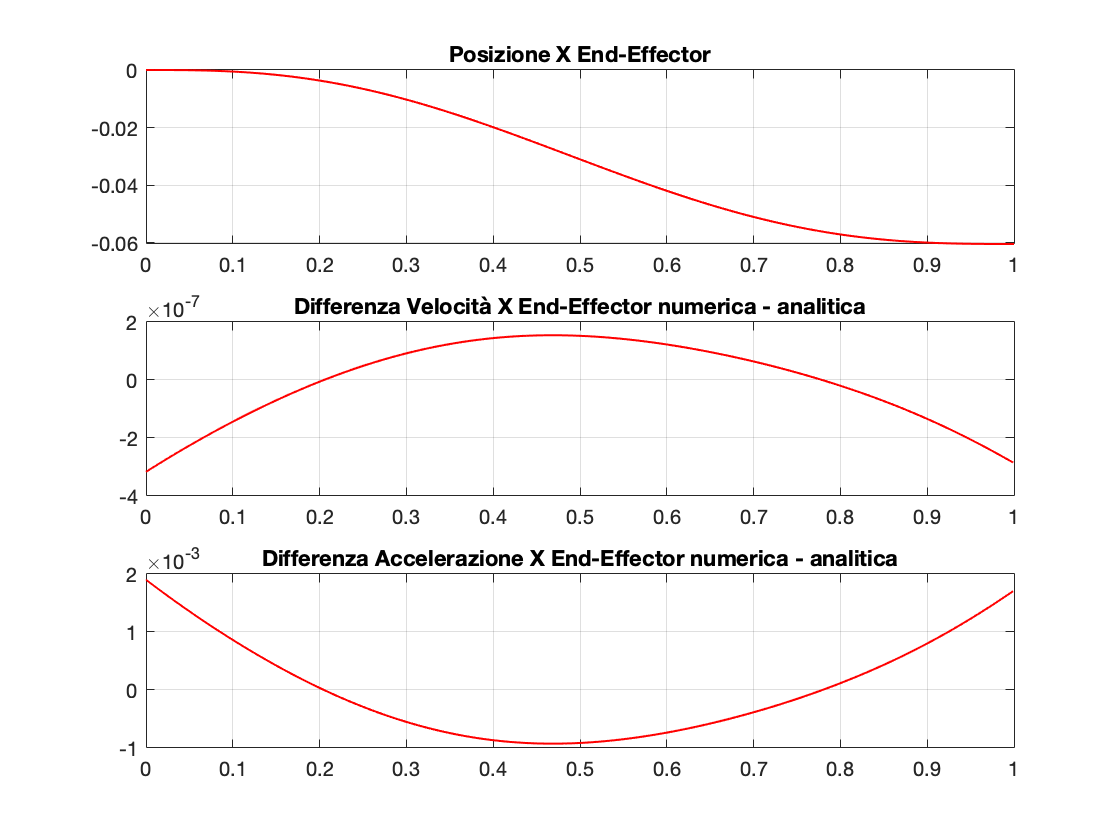

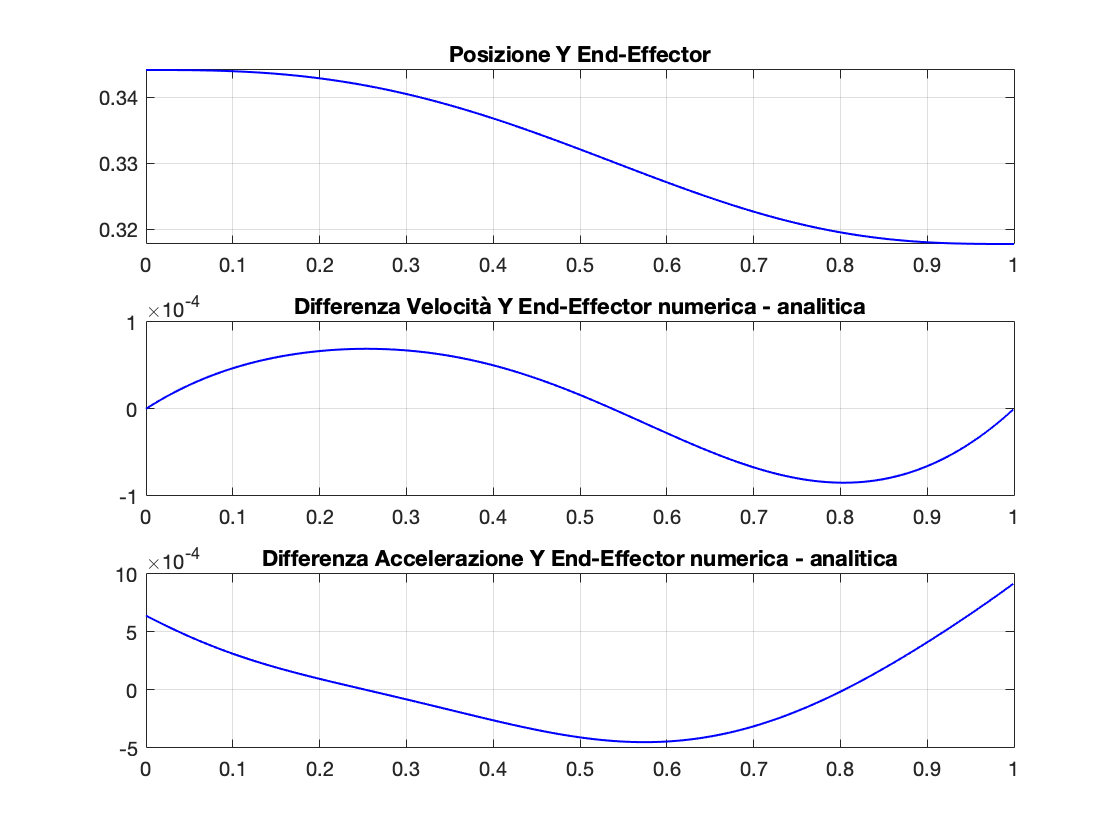

%Plot_EF(PKM,P, P_p34, P_pp34, P_pM)

**Confronto cinematica matlab e adams**

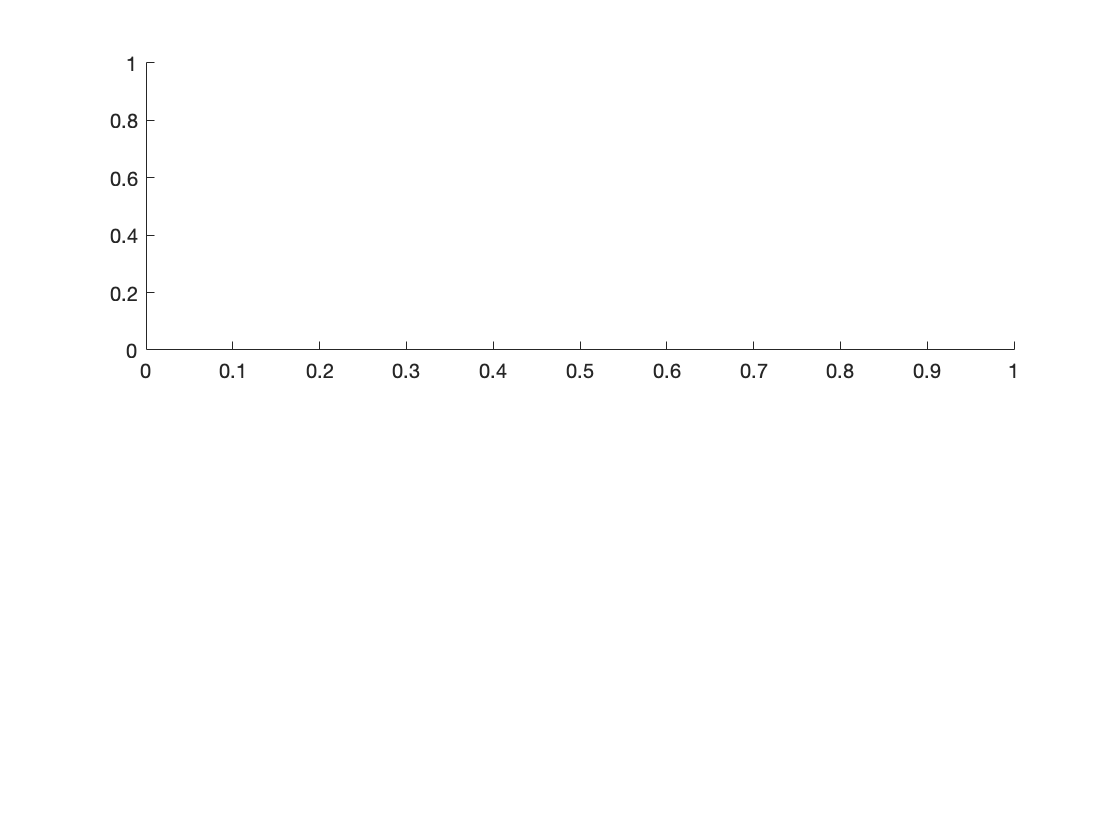

% load PKM_PosEF
% load PKM_VelEF
% load PKM_AccEF
% load PKM_PosE1
% load PKM_VelE1
% load PKM_AccE1
% load PKM_Pa_VelCM
% time = linspace(0,PKM.ta,length(Theta_p));
C1x_p_ad = PKM_Pa_VelCM(:,1);
C1x_p_ad = C1x_p_ad';
C1y_p_ad = PKM_Pa_VelCM(:,2);
C1y_p_ad = C1y_p_ad';
% figure
% subplot(2,1,1);

%plot(time,C2_p(1,:)-C1x_p_ad,'color','b','linewidth',1)
% title('Errore velocità X C1 Matlab-Adams')
% grid on
% 
% subplot(2,1,2); 
% plot(time,C2_p(2,:)-C1y_p_ad,'color','b','linewidth',1)
% title('Errore velocità Y C1 Matlab-Adams')
% grid on
% Matlab_Adams_Cinematica(PKM_PosEF, P, PKM_VelEF, P_p, PKM_AccEF, P_pp, PKM_PosE1, E1, PKM_VelE1, E1_p, PKM_AccE1, E1_pp)

## Cinematica Inversa

**Analisi di posizione**

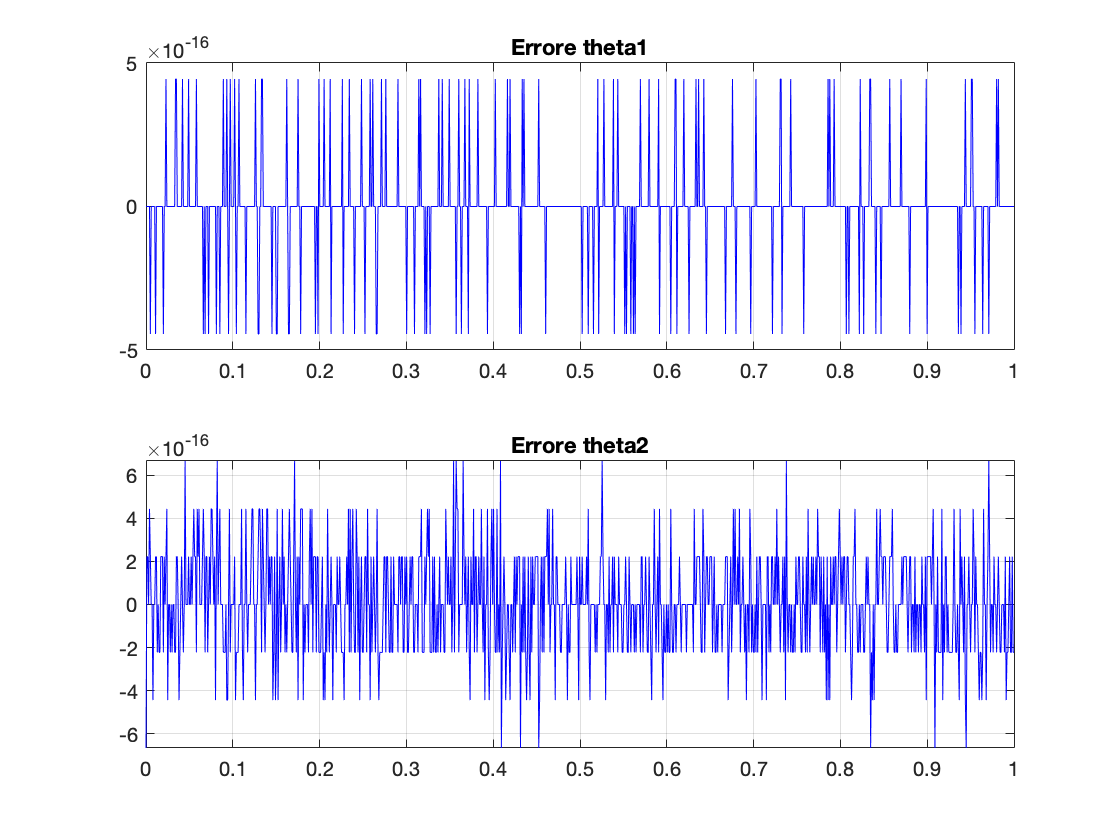

[theta1inv,theta2inv] = Cinematica_Inversa_Posizione(P, PKM, theta1ldm, theta2ldm);
Errore_theta1 = theta1ldm - theta1inv;
Errore_theta2 = theta2ldm - theta2inv;
time = linspace(0,PKM.ta,length(Theta_p));

% figure
% subplot(2,1,1);
% plot(time,Errore_theta1,'color','b')
% title('Errore theta1')
% grid on
% subplot(2,1,2); 
% plot(time,Errore_theta2,'color','b')
% title('Errore theta2')
% grid on

**Rappresentazione grafica**

%animation(PKM.link.d, PKM.link.l,theta1inv,theta2inv,theta3,theta4)

**Analisi di velocità**

Theta_p_inv = Cinematica_Inversa_Velocita(J,P_p);

**Analisi di accelerazione**

% Theta_pp_inv = Cinematica_Inversa_Accelerazione(J_p,J,Theta_p,P_pp);

## Dinamica

**Metodo azioni vicolari**

[C1_AV, C2_AV] = Dinamica(PKM,theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p,theta3_p,theta4_p,...
    theta1ldm_pp,theta2ldm_pp,theta3_pp,theta4_pp,thetavldm_pp)

C1_AV =          0    0.0059    0.0117    0.0175    0.0232    0.0289    0.0346    0.0402    0.0458    0.0514    0.0570    0.0625    0.0679    0.0734    0.0788    0.0841    0.0895    0.0948    0.1000    0.1053    0.1105    0.1156    0.1207    0.1258    0.1309    0.1359    0.1409    0.1459    0.1508    0.1557    0.1606    0.1654    0.1702    0.1750    0.1797    0.1844    0.1890    0.1937    0.1983    0.2028    0.2074    0.2119    0.2163    0.2208    0.2252    0.2296    0.2339    0.2382    0.2425    0.2467


C2_AV =          0    0.0027    0.0054    0.0081    0.0108    0.0134    0.0161    0.0187    0.0213    0.0239    0.0265    0.0290    0.0316    0.0341    0.0366    0.0391    0.0416    0.0441    0.0465    0.0489    0.0514    0.0538    0.0562    0.0585    0.0609    0.0632    0.0655    0.0678    0.0701    0.0724    0.0747    0.0769    0.0791    0.0813    0.0835    0.0857    0.0879    0.0900    0.0922    0.0943    0.0964    0.0985    0.1006    0.1026    0.1047    0.1067    0.1087    0.1107    0.1127    0.1147


**Metodo PLV**

[C1_PLV, C2_PLV, M, K] = Dinamica_PLV(PKM,theta1ldm_p,theta2ldm_p,theta1ldm_pp,theta2ldm_pp,J1,J2,J3,J4,JE,J34,J1p,J2p,J3p,J4p,JEp,J34p)

C1_PLV =          0    0.0055    0.0110    0.0165    0.0220    0.0274    0.0327    0.0381    0.0434    0.0487    0.0539    0.0591    0.0643    0.0695    0.0746    0.0797    0.0847    0.0897    0.0947    0.0997    0.1046    0.1095    0.1143    0.1191    0.1239    0.1287    0.1334    0.1381    0.1428    0.1474    0.1520    0.1566    0.1611    0.1656    0.1701    0.1746    0.1790    0.1834    0.1877    0.1920    0.1963    0.2006    0.2048    0.2090    0.2132    0.2173    0.2215    0.2255    0.2296    0.2336


C2_PLV =          0    0.0026    0.0053    0.0079    0.0104    0.0130    0.0156    0.0181    0.0206    0.0232    0.0257    0.0281    0.0306    0.0330    0.0355    0.0379    0.0403    0.0427    0.0451    0.0474    0.0497    0.0521    0.0544    0.0567    0.0590    0.0612    0.0635    0.0657    0.0679    0.0701    0.0723    0.0745    0.0766    0.0788    0.0809    0.0830    0.0851    0.0872    0.0893    0.0913    0.0934    0.0954    0.0974    0.0994    0.1014    0.1033    0.1053    0.1072    0.1092    0.1111


M =     0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215
   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0

K =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0002    0.0000    0.0002    0.0000    0.0002    0.0000    0.0002    0.0000    0.0002    0.0000    0.0003    0.0000    0.0003    0.0000    0.0003    0.0000    0.0003    0.0000
         0         0   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0002    0.0001   -0.0002    0.0001   -0.0002    0.0001   -0.0003    0.0001   -0.0003    0.0001   -0.0003    0.0001   -0.0004    0.0002   -0.0004    0.0002   -0.0005    0.0002   -0.0005    0.0002   -0.0006    0.0002   -0.0006    0.0003   -0.0007    0.0003   -0.0008    0.0003   -0.0008    0

**Confronto tra i due metodi**

%ErrC1 = C1_PLV(1,:)-C1_AV(1,:);
% ErrC2 = C2_PLV(1,:)-C2_AV(1,:);
% figure
% subplot(2,1,1);
% plot(time(1,:),C1_PLV(1,:),'color','b','linewidth',1)
% title('Coppia theta1 PLV')
% grid on
% subplot(2,1,2);
% plot(time(1,:),C2_PLV(1,:),'color','k','linewidth',1)
% title('Coppia theta2 PLV')
% grid on

**Confronto dinamica Matlab-Adams**

% load PKM_Pa_CoppieNOEF
% Matlab_Adams_Dinamica(PKM_Pa_CoppieNOEF, -C1_PLV, -C2_PLV)

**Dinamica inversa calcolo Coppie**

Condizioni = [theta1ldm(1,1),theta2ldm(1,1),theta1ldm_p(1,1),theta2ldm_p(1,1)]

Condizioni =     2.0944    1.0472         0         0


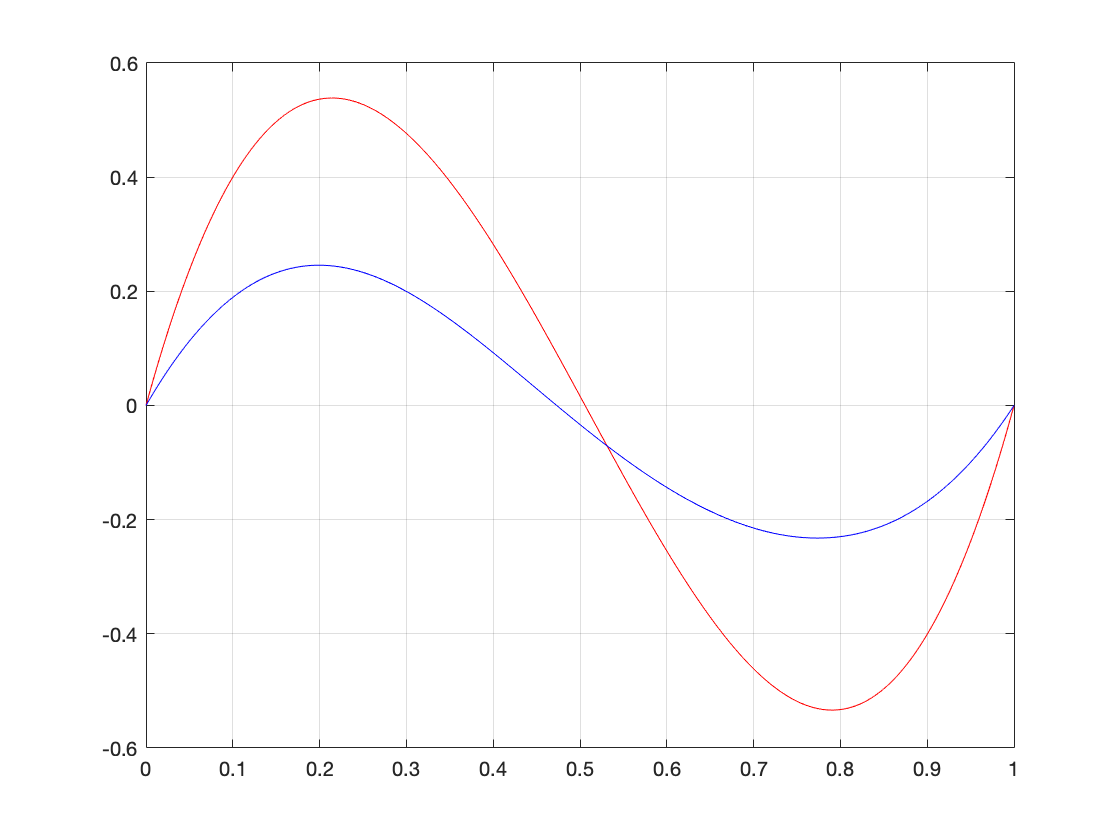

[ThetaInt,Theta_pInt,Theta_ppInt] =  DinamicaInversa([C1_PLV;C2_PLV],Condizioni);
figure
plot(linspace(0,1,1000),C1_PLV,"Color","red")
hold on 
grid on
plot(linspace(0,1,1000),C2_PLV,"Color","b")

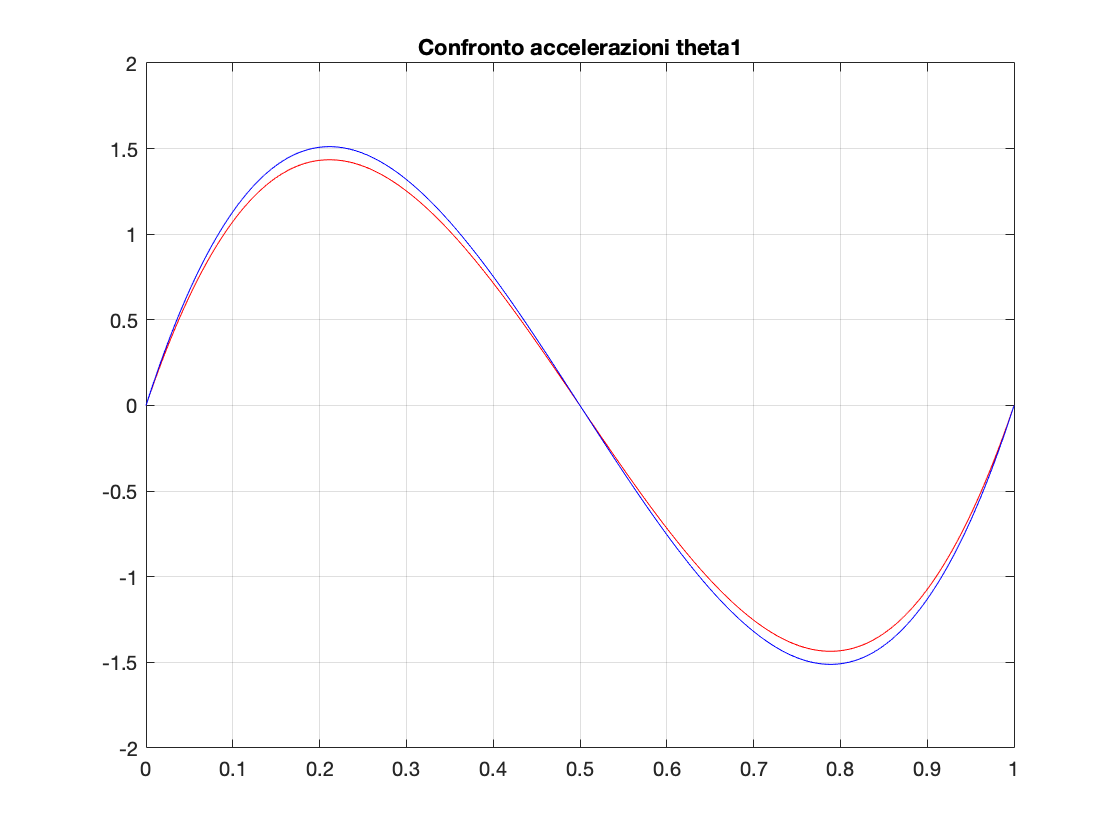

figure
plot(linspace(0,1,1000),Theta_ppInt(1,:),"Color","red")
hold on
grid on
plot(linspace(0,1,1000),theta1ldm_pp(1,:),"Color","b")
title('Confronto accelerazioni theta1')

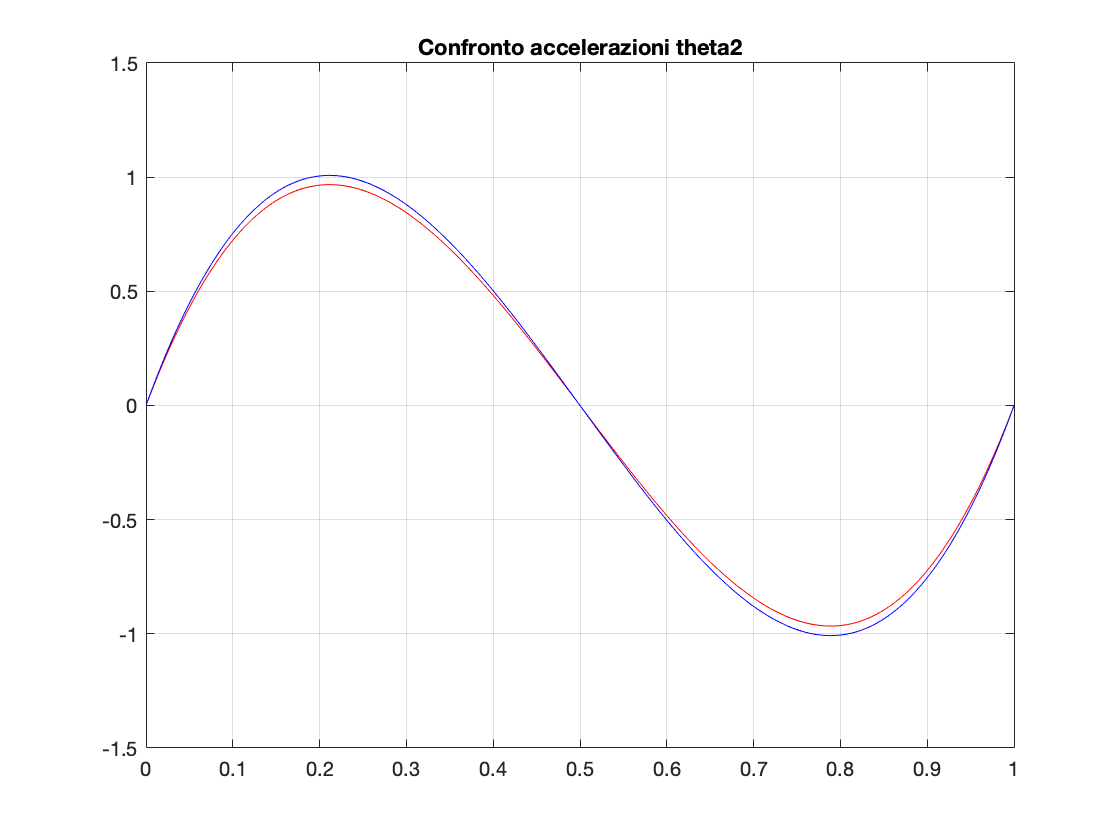

figure
plot(linspace(0,1,1000),Theta_ppInt(2,:),"Color","red")
hold on
grid on
plot(linspace(0,1,1000),theta2ldm_pp(1,:),"Color","b")
title('Confronto accelerazioni theta2')

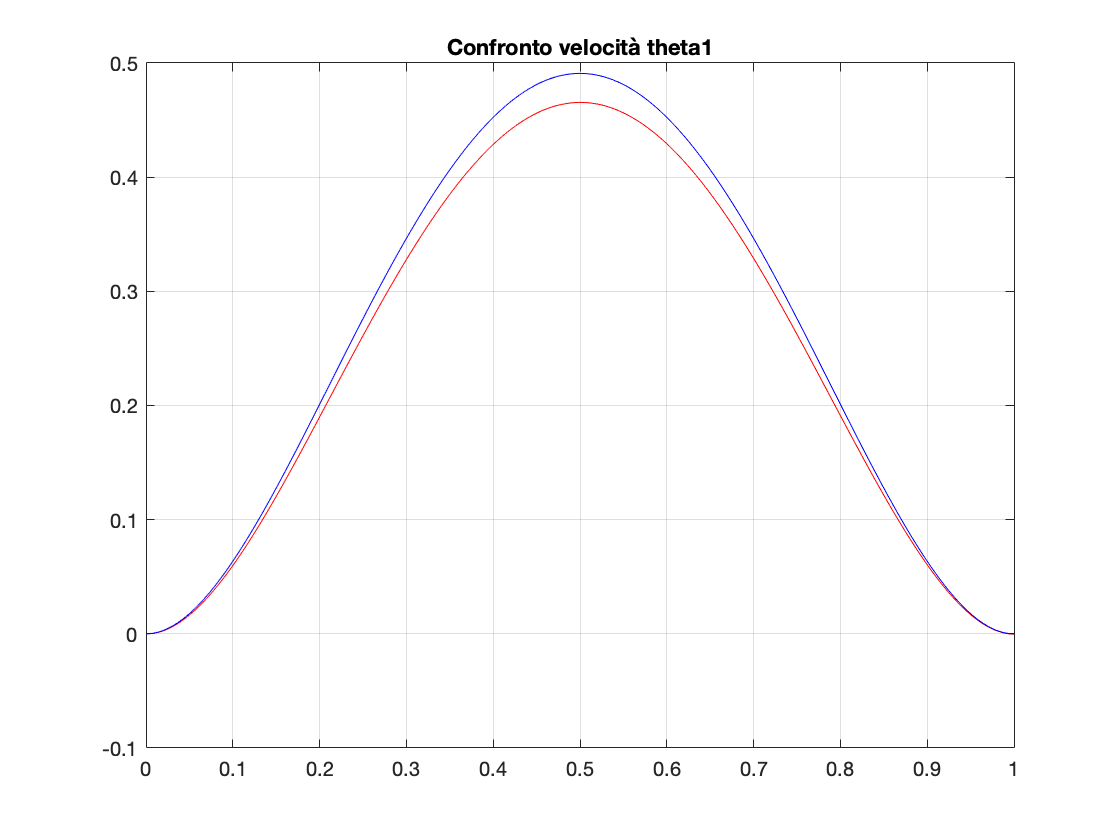

figure
plot(linspace(0,1,1000),Theta_pInt(1,:),"Color","red")
hold on
grid on
plot(linspace(0,1,1000),theta1ldm_p(1,:),"Color","b")
title('Confronto velocità theta1')

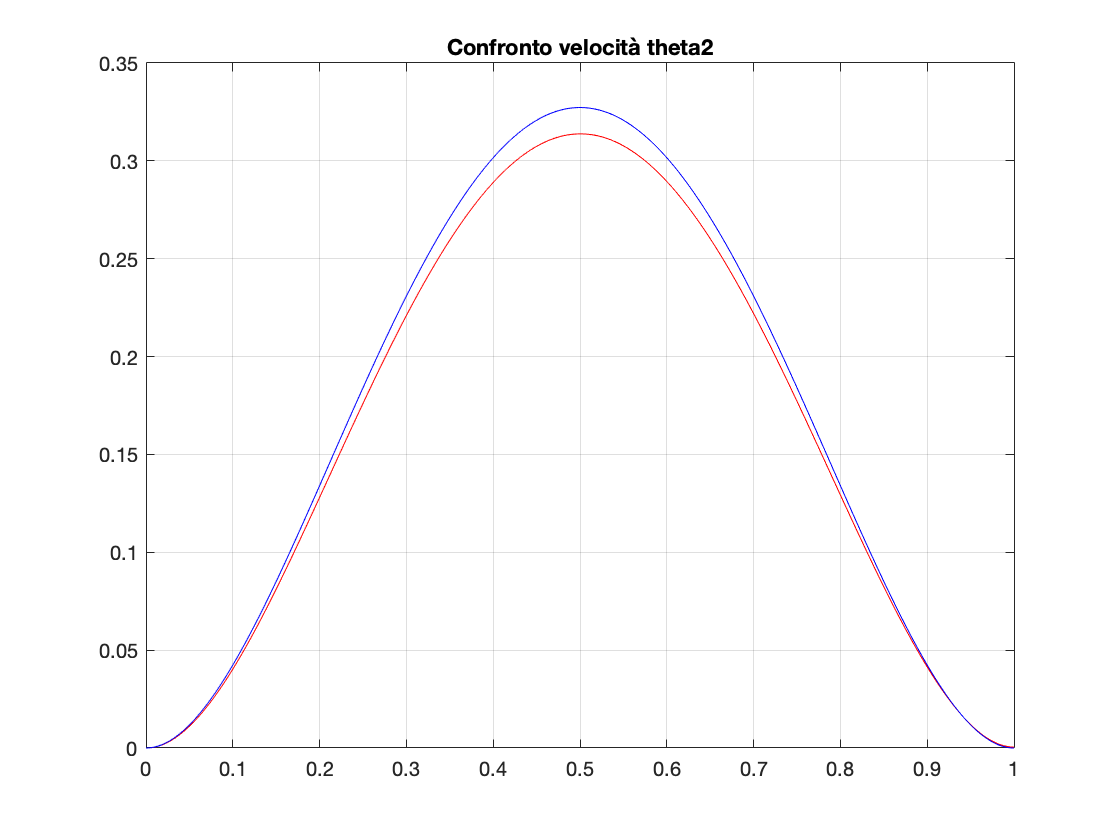

figure
plot(linspace(0,1,1000),Theta_pInt(2,:),"Color","red")
hold on
grid on
plot(linspace(0,1,1000),theta2ldm_p(1,:),"Color","b")
title('Confronto velocità theta2')

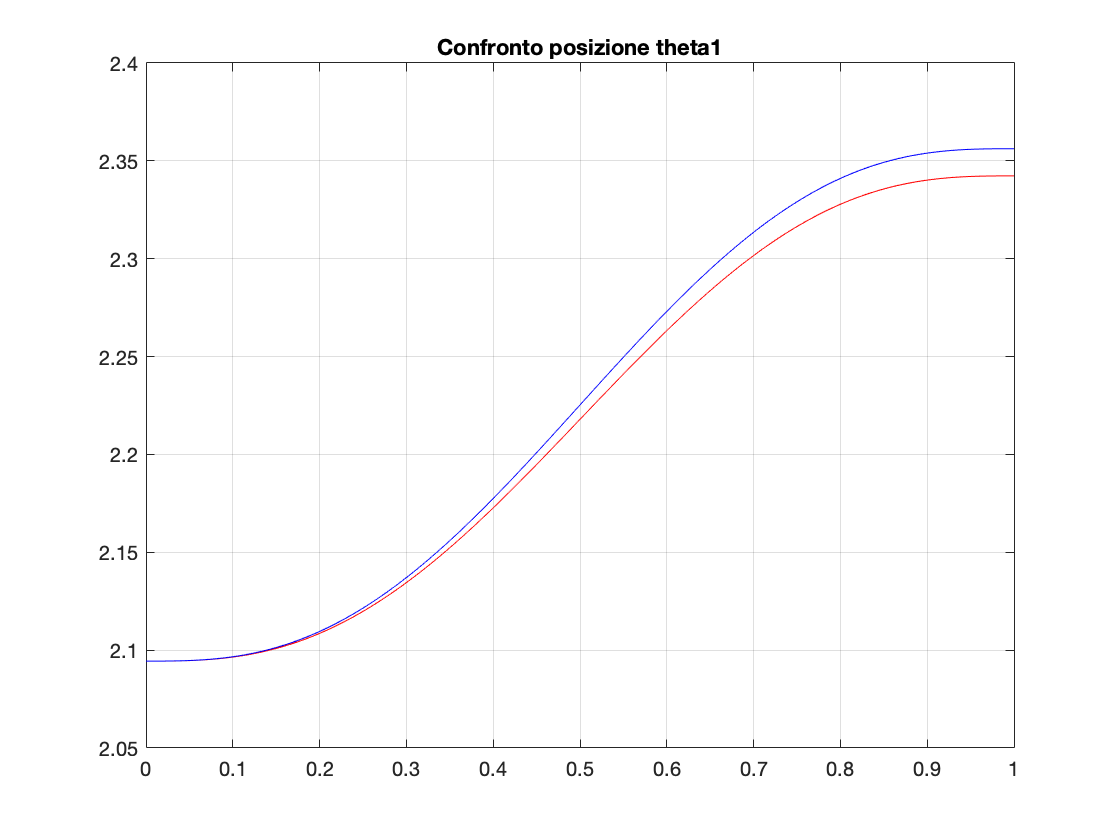


figure
plot(linspace(0,1,1000),ThetaInt(1,:),"Color","red")
hold on
grid on
plot(linspace(0,1,1000),theta1ldm(1,:),"Color","b")
title('Confronto posizione theta1')

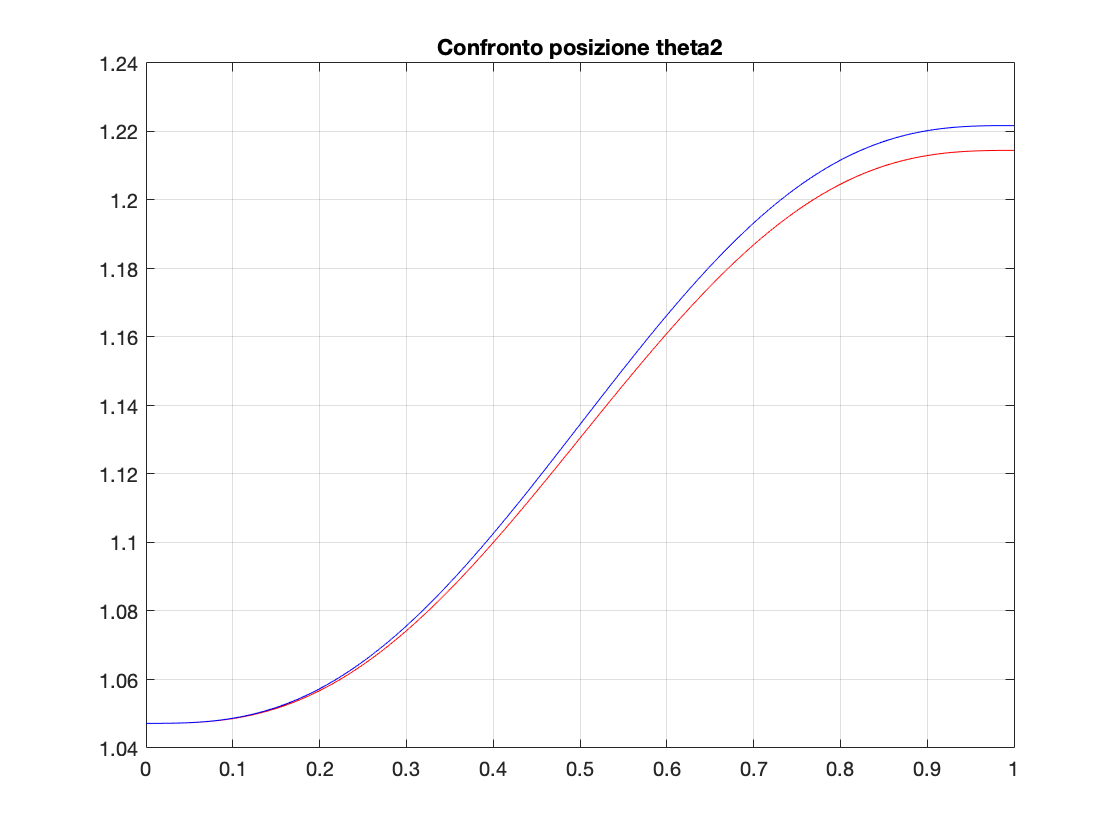

figure
plot(linspace(0,1,1000),ThetaInt(2,:),"Color","red")
hold on
grid on
plot(linspace(0,1,1000),theta2ldm(1,:),"Color","b")
title('Confronto posizione theta2')

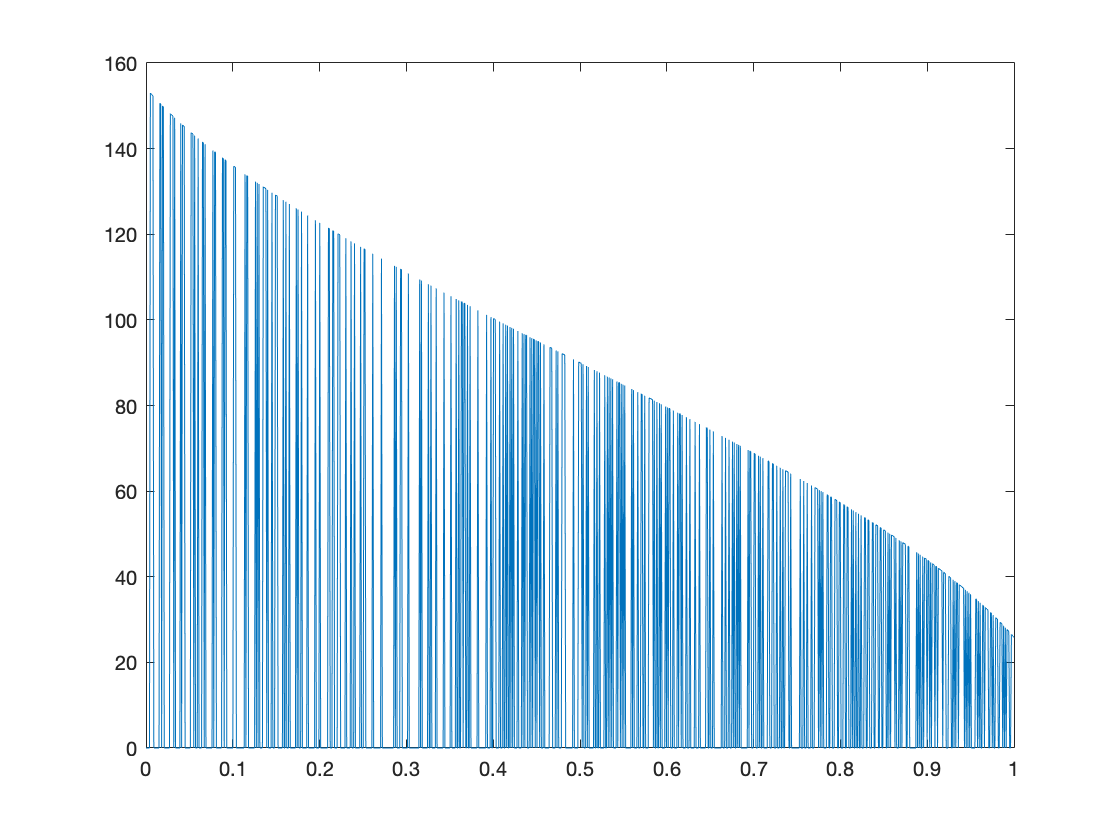

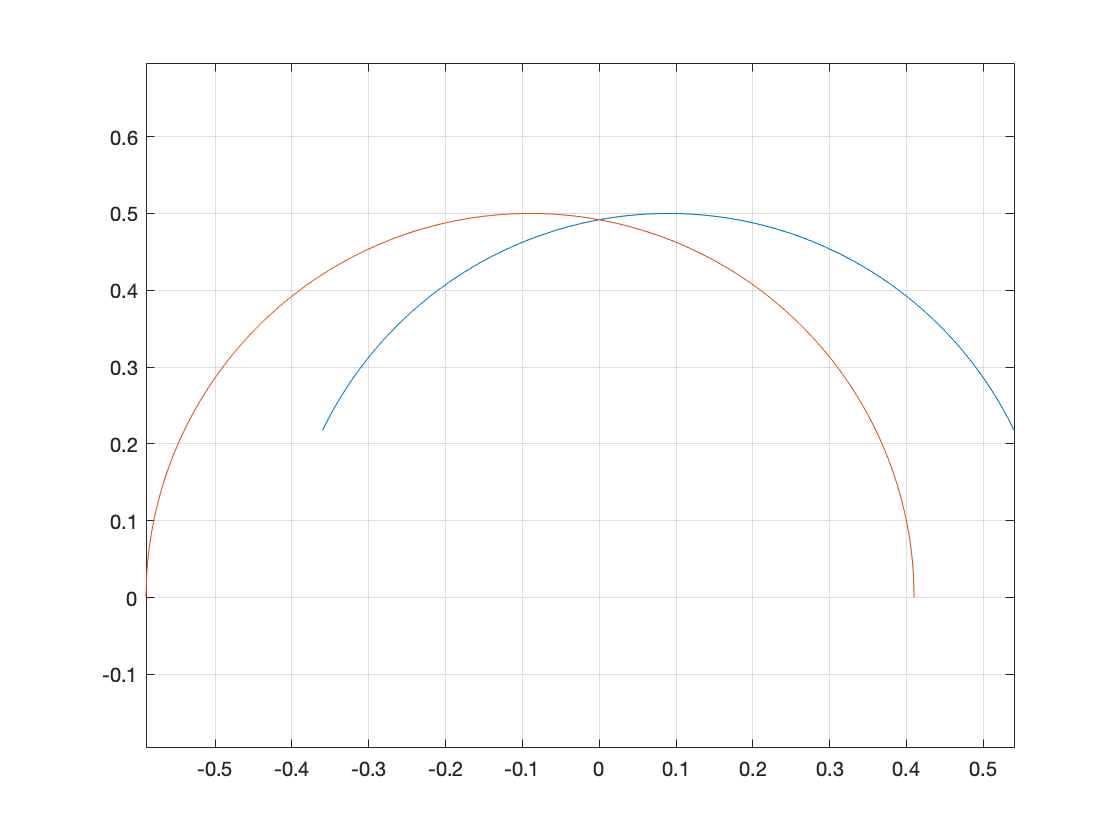

test1 =     3.2663    3.2592    3.2522    3.2452    3.2383    3.2315    3.2247    3.2180    3.2113    3.2046    3.1980    3.1915    3.1850    3.1785    3.1721    3.1657    3.1594    3.1531    3.1468    3.1406    3.1345    3.1283    3.1222    3.1162    3.1101    3.1041    3.0982    3.0923    3.0864    3.0805    3.0747    3.0689    3.0631    3.0574    3.0517    3.0460    3.0403    3.0347    3.0291    3.0236    3.0180    3.0125    3.0070    3.0015    2.9961    2.9907    2.9853    2.9799    2.9746    2.9693


test2 =          0         0         0         0         0    2.6703    2.6664    2.6624    2.6585         0         0         0         0         0         0         0    2.6284    2.6247         0    2.6175    2.6139         0         0         0         0         0         0         0    2.5859    2.5825    2.5791    2.5758         0    2.5691         0         0         0         0         0         0    2.5462         0    2.5398    2.5366    2.5335         0         0         0         0         0


[test1,test2] = Singolarita()